## Letter Dataset Analysis

### Initialise

clear;
clc;
clf;
close all;
% load 3 workspace class instances of LetterDatasetClass:
% - letterDatasetNotNormalised
% - letterDatasetNormalised
% - letterDatasetStandardised (zscore)
load letterDatasetClass.mat;

## Dataset Information: Original Data

- The attributes are not normalised.

- letterDatasetNotNormalised.

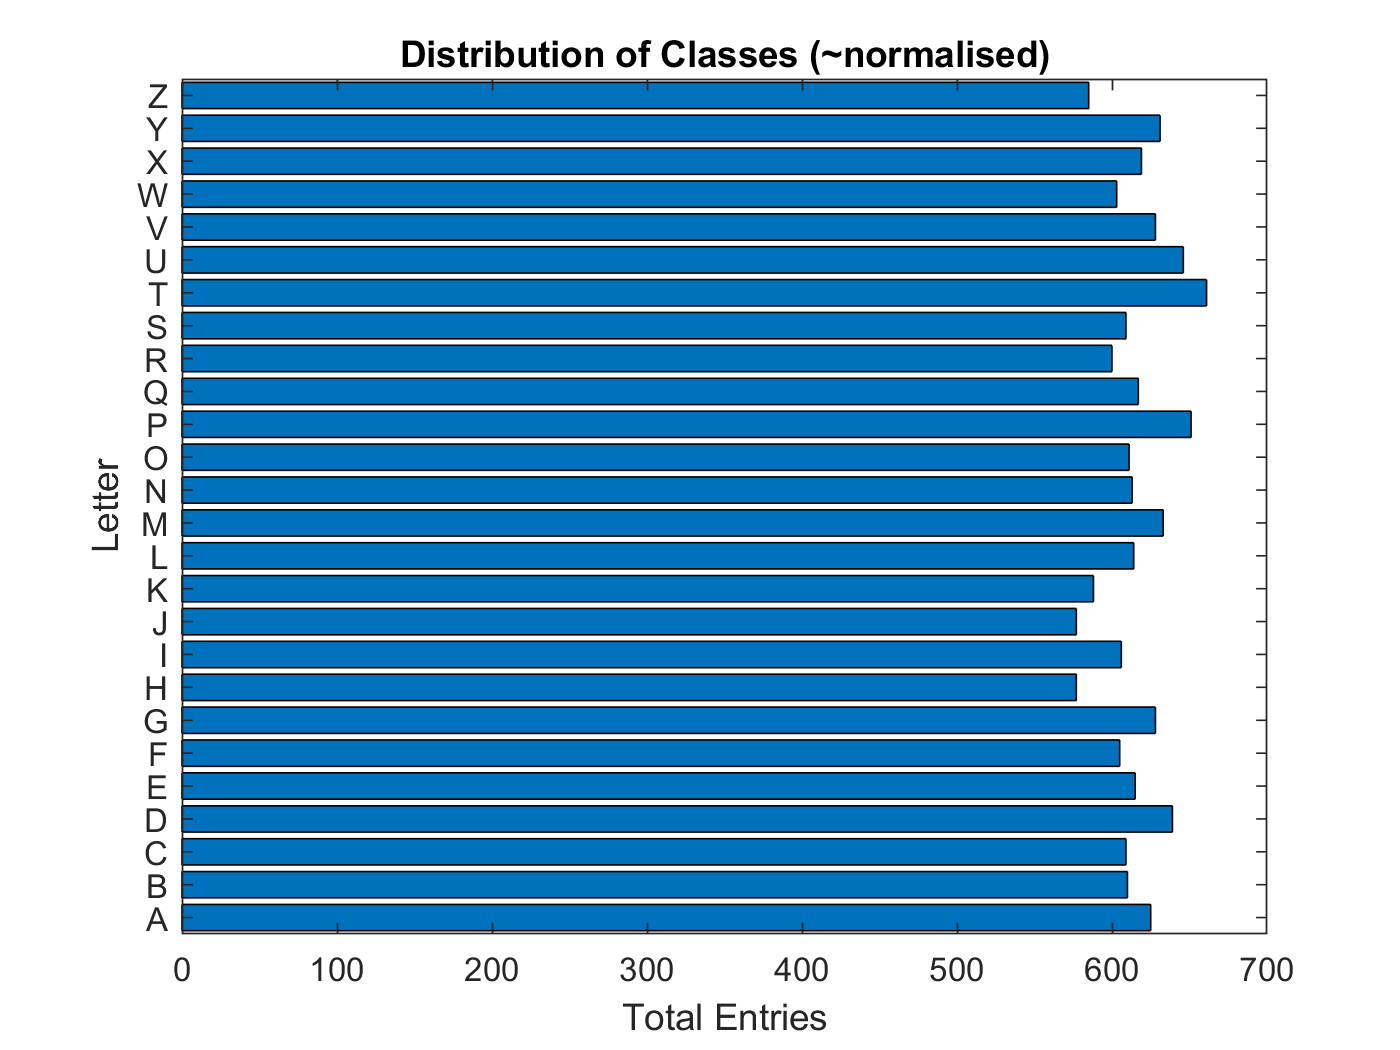

Summary of letter distribution:
Minimum examples per class: 577
Maximum examples per class: 661
Median number of examples per class: 613.5000


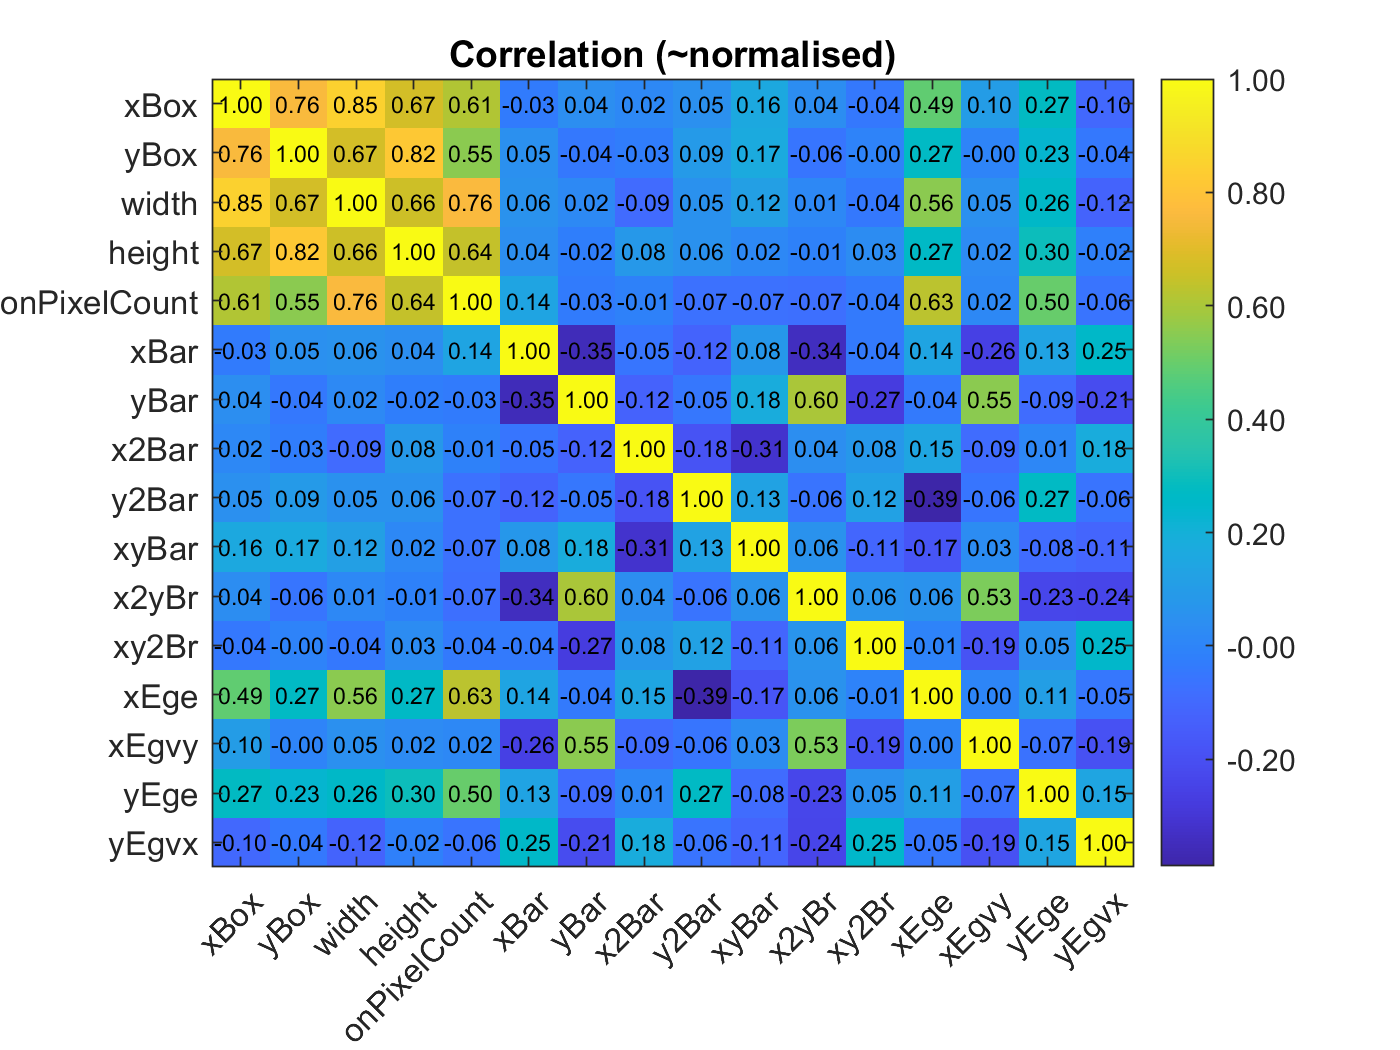

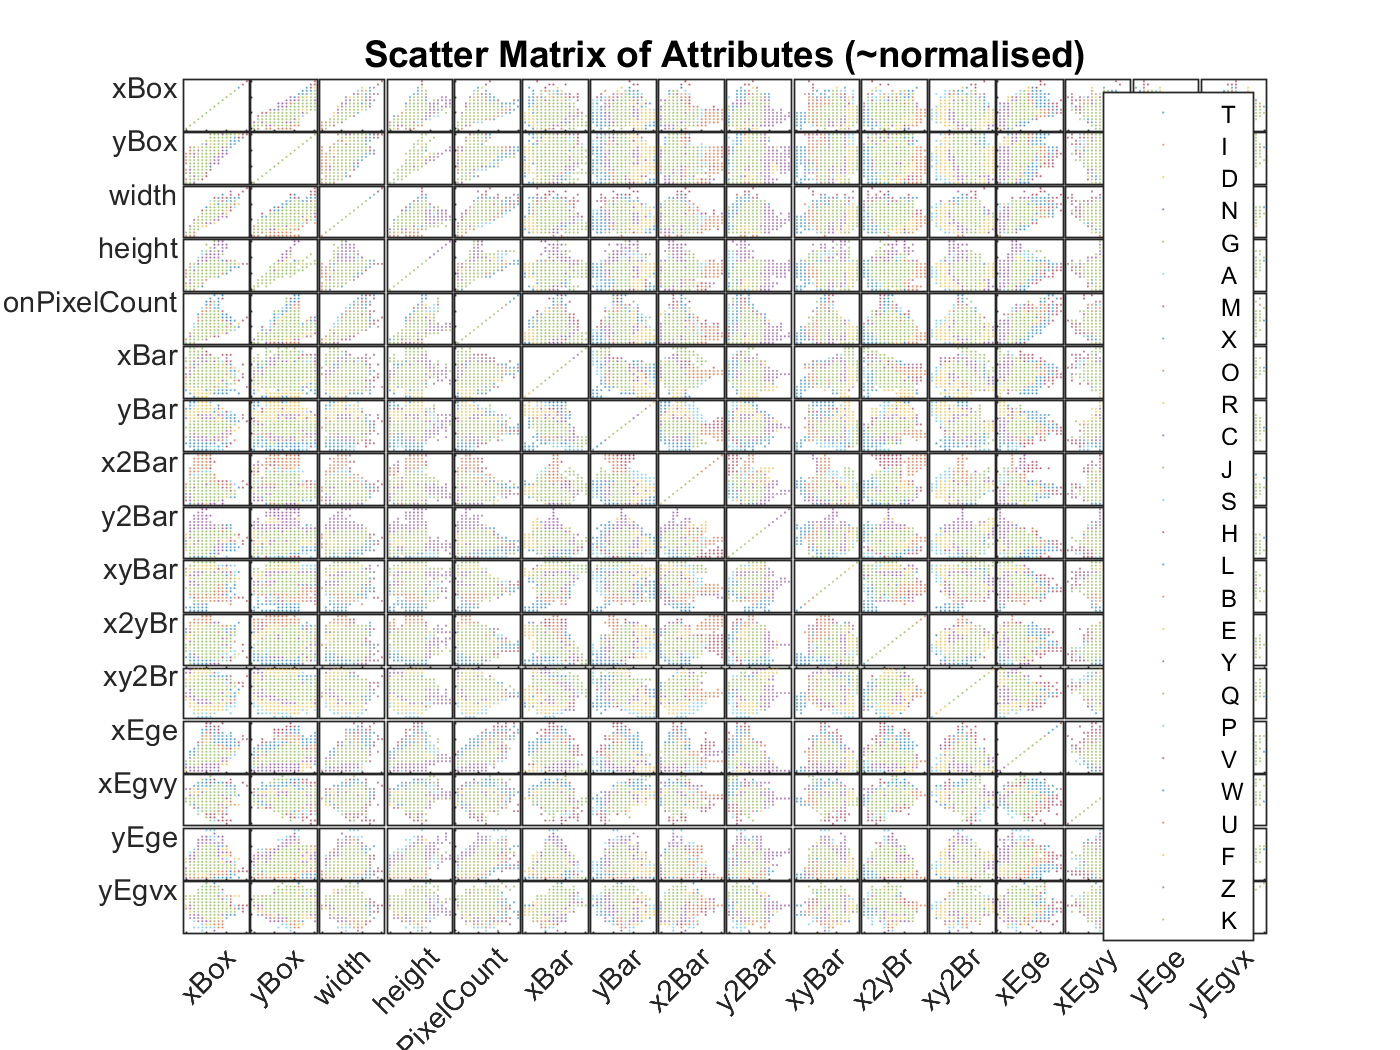

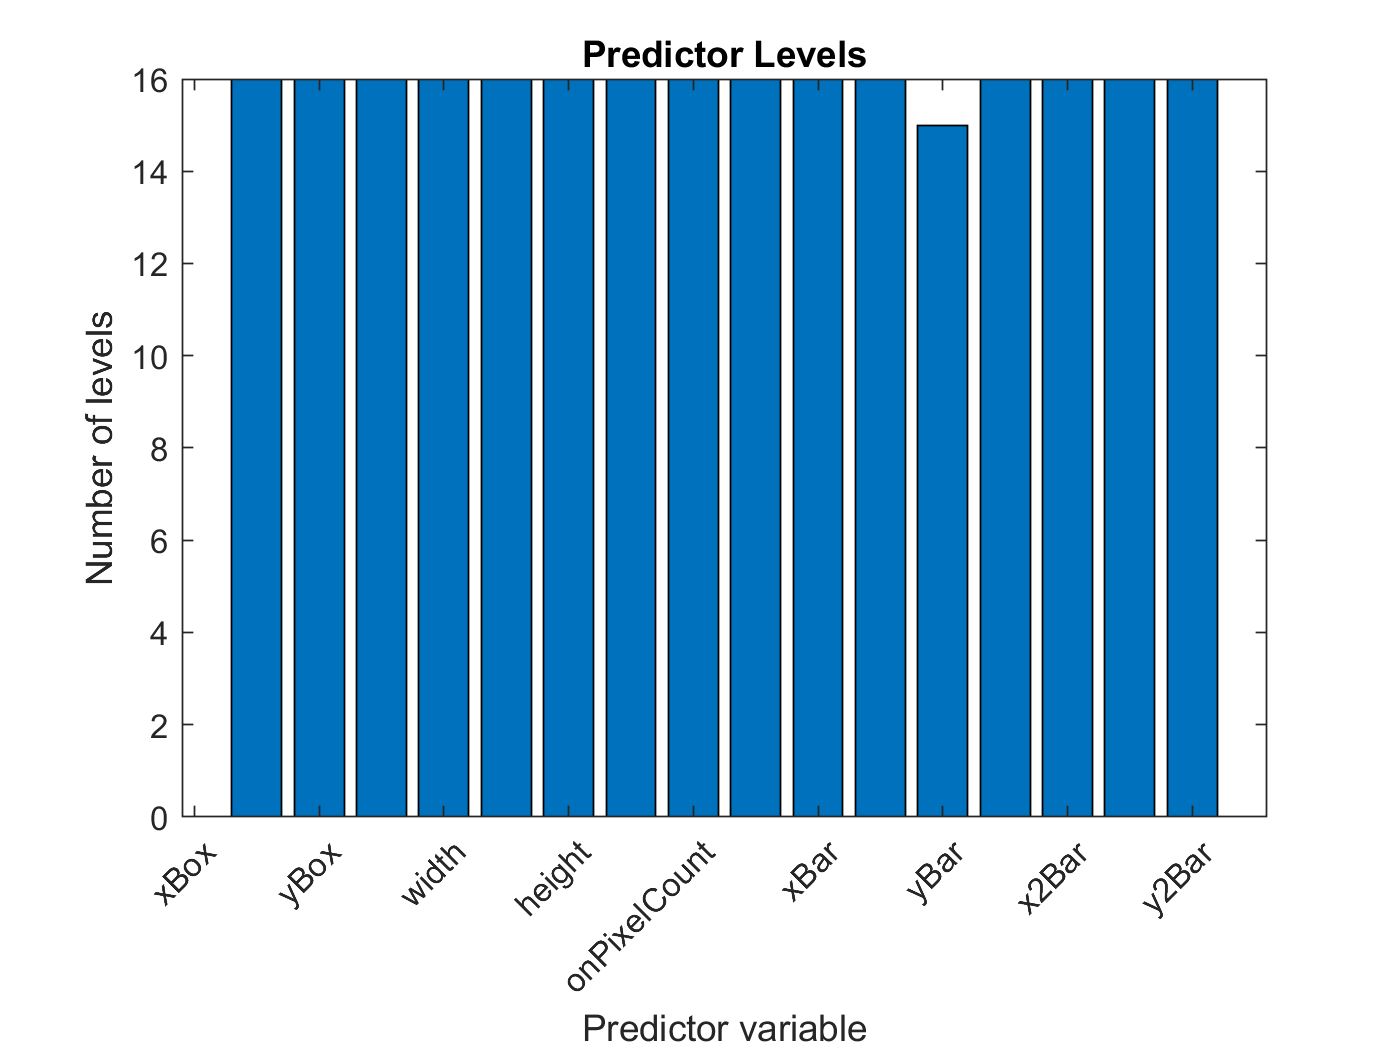

letterDatasetNotNormalised.displayDatasetPlots();

letterDatasetNotNormalised.displayDatasetInformation();

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×16 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×17 table]
                trainTable: [16000×17 table]
                 testTable: [4000×17 table]
              isNormalised: 0
            isStandardised: 0

Training Table Summary:

Variables:

    TargetAscii: 16000×1 cell array of character vectors

    xBox: 16000×1 double

        Values:

            Min           0   
            Median        4   
            Max          15   

    yBox: 16000×1 double

        Values:

            Min           0   
            Median        7   
            Max          15 

## Dataset Information: attributes normalised

- The attributes are normalised.

- letterDatasetNormalised.

letterDatasetNormalised.displayDatasetInformation();

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×16 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×17 table]
                trainTable: [16000×17 table]
                 testTable: [4000×17 table]
              isNormalised: 1
            isStandardised: 0

Training Table Summary:

Variables:

    TargetAscii: 16000×1 cell array of character vectors

    xBox: 16000×1 double

        Values:

            Min             0 
            Median    0.26667 
            Max             1 

    yBox: 16000×1 double

        Values:

            Min             0 
            Median    0.46667 
            Max             

## Dataset Information: attributes standardised

- The attributes are standardised.

- letterDatasetStandardised.

letterDatasetStandardised.displayDatasetInformation();

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×16 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×17 table]
                trainTable: [16000×17 table]
                 testTable: [4000×17 table]
              isNormalised: 0
            isStandardised: 1

Training Table Summary:

Variables:

    TargetAscii: 16000×1 cell array of character vectors

    xBox: 16000×1 double

        Values:

            Min          -2.103
            Median    -0.012309
            Max          5.7372

    yBox: 16000×1 double

        Values:

            Min          -2.129
            Median    -0.010743
            Max        

## Comments

- The dataset distribution of target examples can be treated as balanced (min examples per class 577, max 661).

- There is some strong correlation between attributes which are highly likely to be associated. The scatter matrix confirms this by showing a tendency to plot in a linear grouping. These highly correlated attributes are good candidates for removal, because there is no information gained by keeping them in the dataset [1]. The attributes are xBox, yBox, width, height.

## References

[1] I. Guyon and A. Elisseeff, “An Introduction to Variable and Feature Selection,” *J. Mach. Learn. Res.*, vol. 3, p. 26, 2003.